%% ============================
%  LEITURA E PREPARAÇÃO
% ============================

data = readtable("C:\Users\gabri\Documents\UFMG\TCC\FEMM\lua\resultado\resultados.csv");

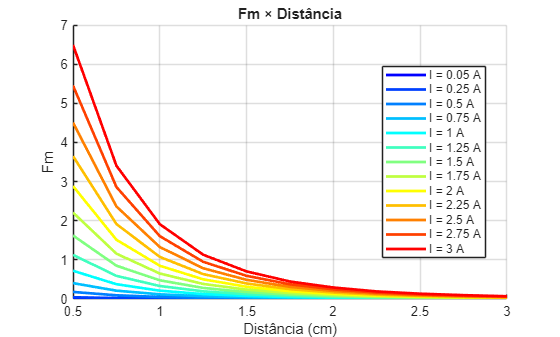



I  = data.Corrente_A_;
d  = -data.Distancia_cm_/100; % Distância negativa em cm (para consistência do conjunto de dados)
L  = data.Indutancia_H_;
Fm = data.ForcaFy_N_; % Força magnética medida (Fm)

% Quero ignorar as distâncias 0,05 e 0,25cm
d_ignorar = [0.0005, 0.0025];
filtro = ~ismember(d, d_ignorar);
% APLICAÇÃO DO FILTRO
I = I(filtro);
d = d(filtro);
Fm = Fm(filtro);

% Valores únicos
corrente_unificada = unique(I); % remover correntes duplicadas
d_unificado = unique(d); % Distâncias únicas medidas

% 1. Definir um colormap com 14 cores (por exemplo, usando a função 'jet')
N = length(corrente_unificada); % N = 14
C = jet(N); % 'jet' é um dos colormaps padrão

% ============================================
% Força x distância
% ============================================
figure;
hold on;
grid on;

for k = 1:length(corrente_unificada)
    Ik = corrente_unificada(k);

    mask = (I == Ik);

    % sorted by distance
    [d_sorted, idx] = sort(d(mask));
    Fm_sorted = Fm(mask);
    Fm_sorted = Fm_sorted(idx);

    plot(d_sorted*100, Fm_sorted, 'Color', C(k,:), 'LineWidth', 2);
end


xlabel('Distância (cm)');
ylabel('Fm');
title('Fm × Distância');
legend("I = " + string(corrente_unificada) + " A", 'Location','best');
hold off;




%% ============================
% 2. REGRESSÃO DO MODELO FM
%     Fm = K_fm * (I^2 / x^2)
% ============================


% Variável dependente Y é a Força medida (Fy)
Y_Fm = Fm;

% Variável independente X é a razão transformada I^2 / x^2
% Usamos o vetor 'd' (distância em cm) para consistência.
X_Fm = (I.^2) ./ (d.^2);

% --- Realiza a regressão usando o operador barra invertida ---
K_Fm = X_Fm \ Y_Fm;

% Calcula a qualidade do ajuste (R-quadrado)
Y_Fm_modelo = X_Fm * K_Fm;
SS_residual_Fm = sum((Y_Fm - Y_Fm_modelo).^2);
SS_total_Fm = sum((Y_Fm - mean(Y_Fm)).^2);
R_sq_Fm = 1 - (SS_residual_Fm / SS_total_Fm);


disp('===========================================');

disp('🧲 RESULTADOS DA REGRESSÃO FM (Operador Barra Invertida)');

🧲 RESULTADOS DA REGRESSÃO FM (Operador Barra Invertida)


disp('===========================================');

disp(['Valor de K_fm ajustado: ', num2str(K_Fm)]);

Valor de K_fm ajustado: 1.8632e-05


disp(['R-quadrado (Qualidade do Ajuste): ', num2str(R_sq_Fm)]);

R-quadrado (Qualidade do Ajuste): 0.99224


disp(' ');

fprintf('Expressão Final Fm(x, I) = %.7f * (I^2 / x^2)\n', K_Fm);

Expressão Final Fm(x, I) = 0.0000186 * (I^2 / x^2)


disp('===========================================');

# VALIDAÇÃO DO MODELO

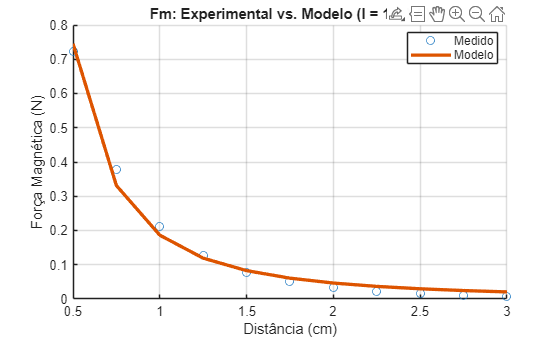

% Altere este índice para selecionar uma fatia de corrente diferente.
index_atual = 5; %I = 1 A


% Corrente selecionada
Ik = corrente_unificada(index_atual); % Valor da corrente selecionada


% Ordenar por distância
ordenador = I == Ik;
[d_ordenado, idx] = sort(d(ordenador));
Fm_ordenado = Fm(ordenador);
Fm_experimental = Fm_ordenado(idx); % A força magnética experimental é Fm


% Calcula a previsão do modelo para as distâncias únicas
% Fm_modelo = K * (I^2 / x^2)
Fm_modelo = K_Fm * ((Ik^2) ./ (d_unificado.^2));


% ============================================
% 4. Plotagem da Comparação
% ============================================
figure;
hold on;
grid on;


% Plotar Dados Experimentais (Círculos)
% Usar Fy_experimental como os dados Y
plot(d_unificado*100, Fm_experimental, 'o', 'MarkerSize', 6, 'DisplayName', 'Medido');
     
% Plotar Previsão do Modelo (Linha Sólida)
% Usar Fm_modelo como os dados Y
plot(d_unificado*100, Fm_modelo, '-', 'LineWidth', 2.5, 'DisplayName', 'Modelo');


% ============================================
% 5. Rótulos e Personalização
% ============================================
xlabel('Distância (cm)');
ylabel('Força Magnética (N)');
title(sprintf('Fm: Experimental vs. Modelo (I = %.2f A)', Ik));
legend('Location','best');
hold off;